savenam = foldernam + 'Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat"

load(savenam)
PS_traj_21 = PS_traj;
savenam = foldernam + 'Data\1-CCRN-1-cat_descend_3_1_straightIC_500_05-Dec-2023.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_3_1_straightIC_500_05-Dec-2023.mat"

load(savenam)
PS_traj_31 = PS_traj;

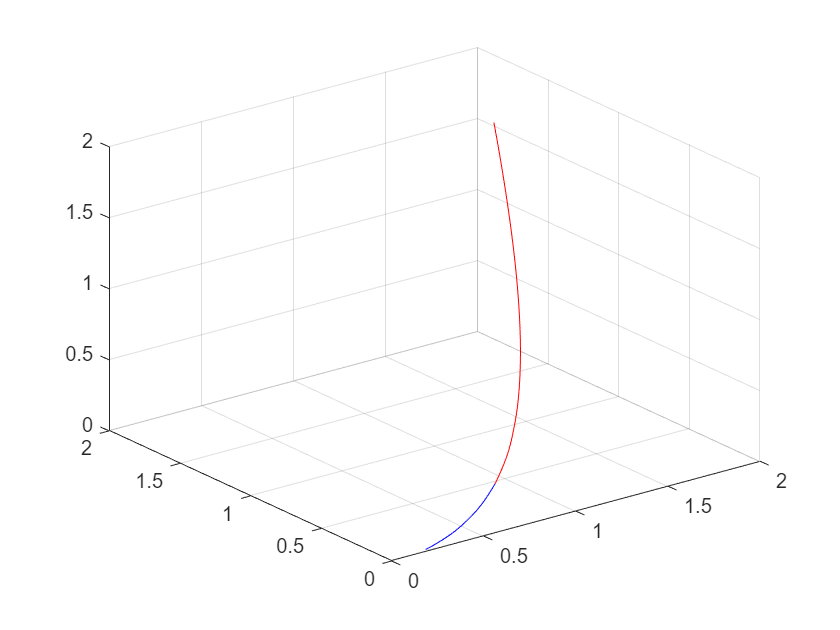

figure()
PS_traj = PS_traj_21;
plot3(PS_traj(:,1),PS_traj(:,2),PS_traj(:,3),'b')
hold on
PS_traj = PS_traj_31;
plot3(PS_traj(:,1),PS_traj(:,2),PS_traj(:,3),'r')
hold off
grid on

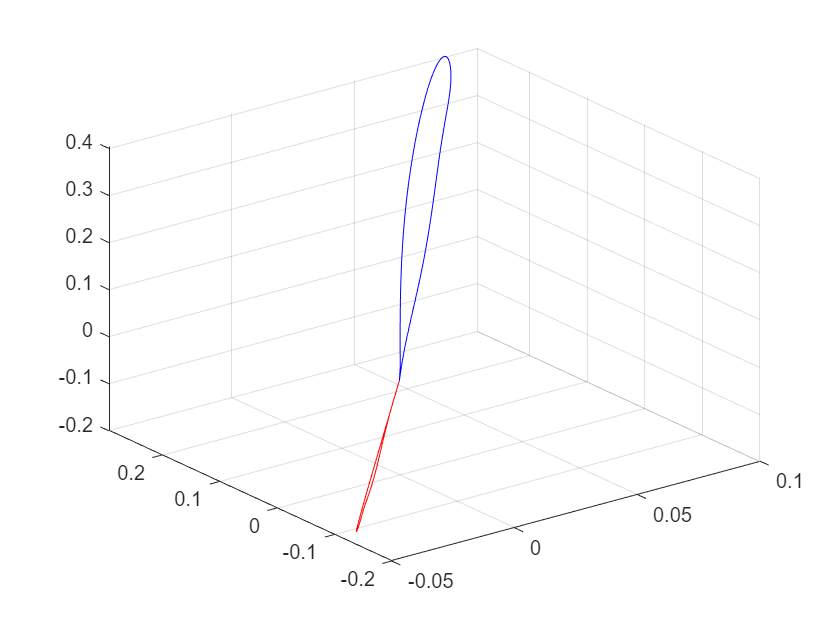

figure()
PS_traj = PS_traj_21;
plot3(PS_traj(:,4),PS_traj(:,5),PS_traj(:,6),'b')
hold on
PS_traj = PS_traj_31;
plot3(PS_traj(:,4),PS_traj(:,5),PS_traj(:,6),'r')
hold off
grid on

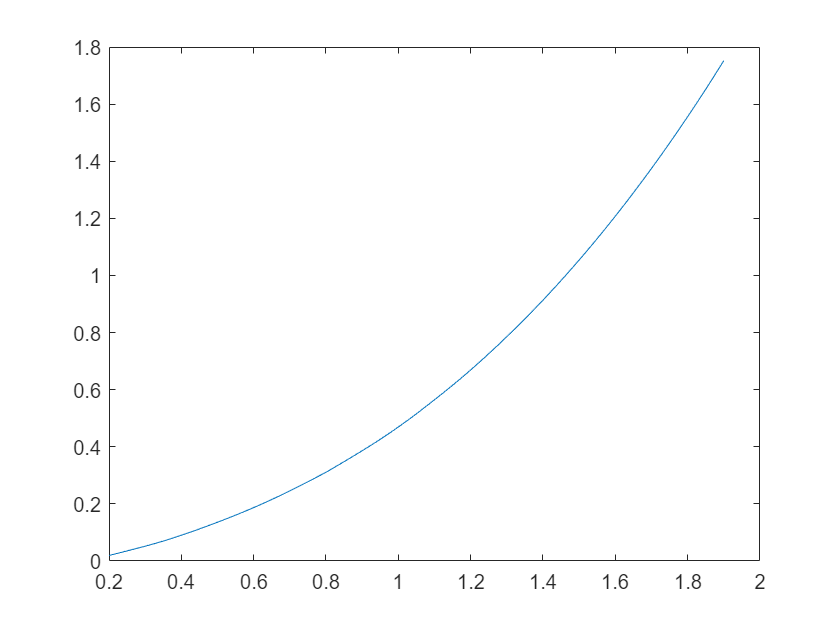

PS_flip = flip(PS_traj_31);
PS_conc = [PS_traj_21 ; PS_flip(2:end,:)];
figure()
plot(PS_conc(:,1),PS_conc(:,2))

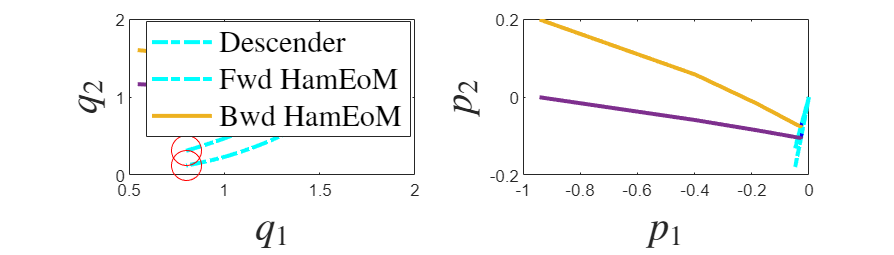

a =    2.195468205891743


a = ham_closest_approach(PS_traj,S_traj,t_traj,...
    dHamdp_fun, dHamdq_fun, "asdf",0,'asf')

%graph of CRN
rxn_rate

rxn_rate =    1.000000000000000   2.000000000000000   0.147600000000000
   2.000000000000000   1.000000000000000   1.000000000000000
   3.000000000000000   4.000000000000000   1.000000000000000
   4.000000000000000   3.000000000000000   2.060000000000000
   5.000000000000000   6.000000000000000   1.000000000000000
   6.000000000000000   5.000000000000000   2.060000000000000
   4.000000000000000   7.000000000000000   2.900000000000000
   7.000000000000000   4.000000000000000   1.000000000000000


%input and output stoichiometric matrices
inp_stoich = comp_vec(rxn_rate(:,1),:)

inp_stoich =      0     0     0
     1     0     0
     2     0     0
     0     1     0
     1     1     0
     0     0     1
     0     1     0
     1     1     0


out_stoich = comp_vec(rxn_rate(:,2),:)

out_stoich =      1     0     0
     0     0     0
     0     1     0
     2     0     0
     0     0     1
     1     1     0
     1     1     0
     0     1     0


stoich_mat = out_stoich-inp_stoich

stoich_mat =      1     0     0
    -1     0     0
    -2     1     0
     2    -1     0
    -1    -1     1
     1     1    -1
     1     0     0
    -1     0     0


%monomials for reactions
rxn_inp = {};
for i = 1:size(rxn_rate,1)
    y_in = comp_vec(rxn_rate(i,1),:)';
    rxn_inp{end+1} = rxn_rate(i,3)*prod(q.'.^y_in);
end

celldisp(rxn_inp)

 
rxn_inp{1} =
 


$$0.1476$$

 
 
rxn_inp{2} =
 


$$q_{1}$$

 
 
rxn_inp{3} =
 


$${q_{1}}^{2}$$

 
 
rxn_inp{4} =
 


$$2.0600\,q_{2}$$

 
 
rxn_inp{5} =
 


$$q_{1}\,q_{2}$$

 
 
rxn_inp{6} =
 


$$2.0600\,q_{3}$$

 
 
rxn_inp{7} =
 


$$2.9000\,q_{2}$$

 
 
rxn_inp{8} =
 


$$q_{1}\,q_{2}$$


%get effective reaction rates by subtracting reverse rate
num_rxn = floor(size(rxn_rate,1)/2);
eff_rate = {};
stoic_red = [];
for i = 1:num_rxn
    eff_rate{end+1} = rxn_inp{2*(i-1)+1} - rxn_inp{2*(i)};
    stoic_red = [stoic_red; stoich_mat(2*(i-1)+1,:)];
end
celldisp(eff_rate)

 
eff_rate{1} =
 


$$0.1476-q_{1}$$

 
 
eff_rate{2} =
 


$${q_{1}}^{2}-2.0600\,q_{2}$$

 
 
eff_rate{3} =
 


$$q_{1}\,q_{2}-2.0600\,q_{3}$$

 
 
eff_rate{4} =
 


$$2.9000\,q_{2}-q_{1}\,q_{2}$$

stoic_red

stoic_red =      1     0     0
    -2     1     0
    -1    -1     1
     1     0     0


%find chemical potential across each reaction
iter_max = size(PS_conc,1);
diss_vec = zeros(iter_max,1);
diss_arr ={};

for j = 1:num_rxn
    for i = 1:iter_max
        diss_vec(i) = PS_conc(i,4:6)*stoic_red(j,:)'*subs(eff_rate{j},q,PS_conc(i,1:3));
    end
    diss_arr{end+1} = diss_vec;
end


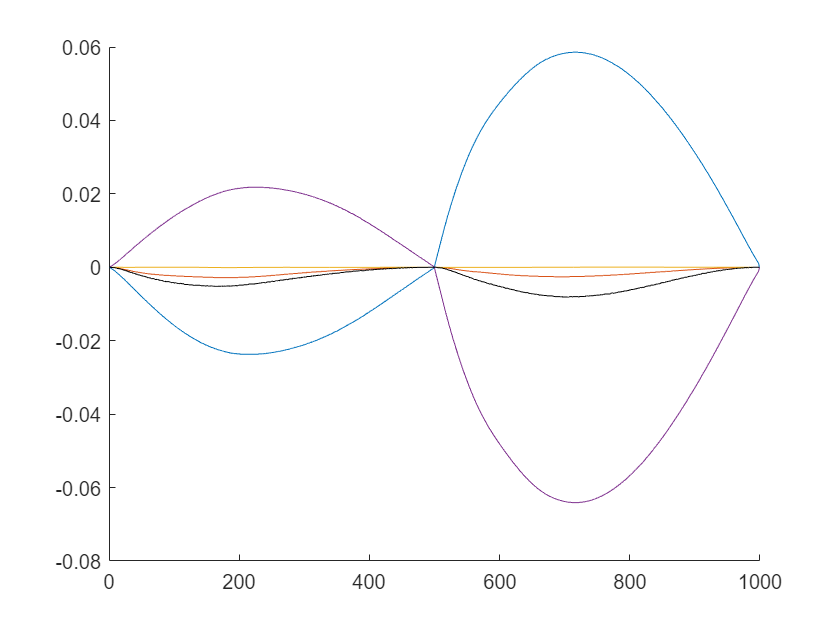

figure()
legend_lst = [];
sum = zeros(size(diss_arr{1}));

hold on
for i = 1:num_rxn
    plot(diss_arr{i})
    legend_lst =[legend_lst, string(i)];
    sum = sum + diss_arr{i};
end
plot(sum,'k')

legend_lst =[legend_lst, "Total"];

%find net rxn velocity
iter_max = size(PS_conc,1);
diss_vec = zeros(iter_max,1);
rate_arr ={};

for j = 1:num_rxn
    for i = 1:50:iter_max
        diss_vec(i) = subs(eff_rate{j},q,PS_conc(i,1:3));
    end
    rate_arr{end+1} = diss_vec;
end

subs(eff_rate{1},q,PS_conc(541,1:3))

$$ans = -0.8461$$

eff_rate_1 = matlabFunction(eff_rate{1},'Vars',{q});
eff_rate_2 = matlabFunction(eff_rate{2},'Vars',{q});
eff_rate_3 = matlabFunction(eff_rate{3},'Vars',{q});
eff_rate_4 = matlabFunction(eff_rate{4},'Vars',{q});

ans =    -0.0525
   -0.0539
   -0.0553
   -0.0567
   -0.0580
   -0.0594
   -0.0608
   -0.0622
   -0.0636
   -0.0650


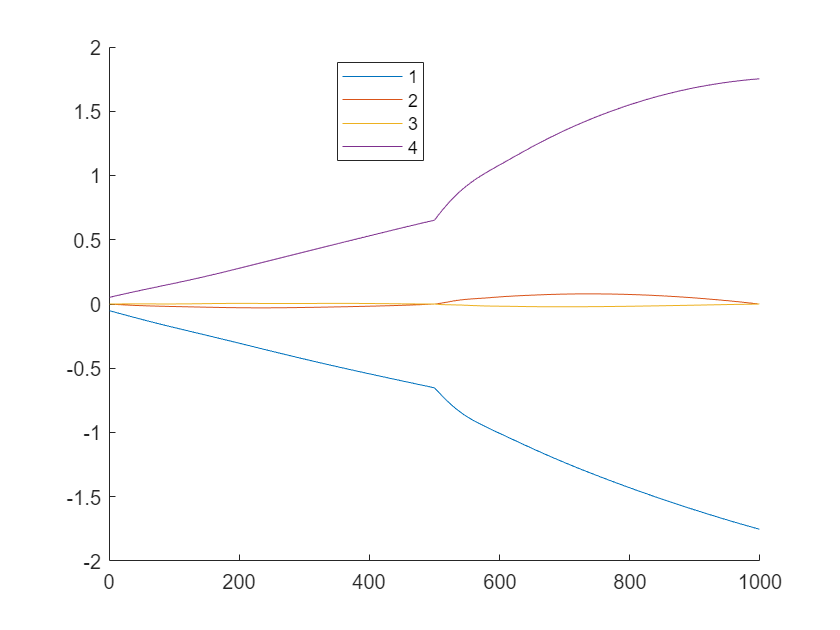

figure()
legend_lst = [];
sum = zeros(size(diss_arr{1}));

hold on
plot(eff_rate_1(PS_conc(:,1:3)))
plot(eff_rate_2(PS_conc(:,1:3)))
plot(eff_rate_3(PS_conc(:,1:3)))
plot(eff_rate_4(PS_conc(:,1:3)))

legend(["1" "2" "3" "4"],'location','best')

PS_traj_31(1,:)

ans =     1.9000    1.7525    1.6164         0         0         0


PS_traj_31(end,:)

ans =     0.7999    0.3106    0.1206         0         0         0


PS_traj_21(end,:)

ans =     0.7999    0.3106    0.1206         0         0         0


PS_traj_21(1,:)

ans =     0.2001    0.0194    0.0019         0         0         0


PS_conc =     0.2001    0.0194    0.0019         0         0         0
    0.2015    0.0199    0.0020    0.0030    0.0111    0.0196
    0.2029    0.0203    0.0020    0.0049    0.0194    0.0285
    0.2043    0.0207    0.0020    0.0068    0.0276    0.0372
    0.2056    0.0212    0.0021    0.0087    0.0358    0.0460
    0.2070    0.0216    0.0021    0.0106    0.0439    0.0547
    0.2084    0.0221    0.0022    0.0125    0.0519    0.0633
    0.2098    0.0225    0.0022    0.0143    0.0598    0.0718
    0.2112    0.0229    0.0023    0.0162    0.0676    0.0802
    0.2126    0.0234    0.0023    0.0180    0.0753    0.0885
